hold on
grid on
x_1 = [11.46, 22.84, 35.96, 47.50, 59.27, 69.34, 80.50];
x_2 = [87.16, 94.36, 102.03, 109.16, 115.66];
y_1 = [18, 37, 59, 78, 98, 118, 139];
y_2 = [157, 196, 235, 274, 314];
ylim([0,340])
point_1 = scatter(x_1, y_1,'blue');
point_2 = scatter(x_2, y_2, 'green');
coeff_1 = polyfit(x_1,y_1, 1)

coeff_1 =     1.7420   -3.2032


y1 = 0;
xi = min(0):0.1:max(120)

xi =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


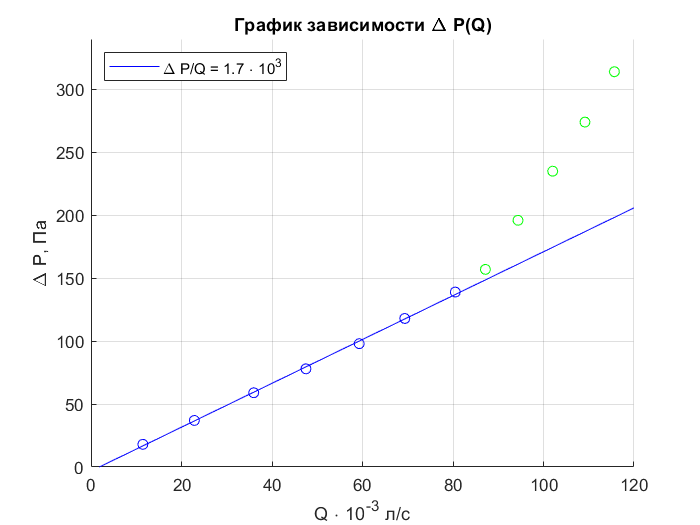

for k=0:1
    y1 = y1 + coeff_1(1-k+1) * xi.^k;
end
gr_1 = plot(xi, y1,'blue'); 
title("График зависимости \Delta P(Q)")
xlabel('Q \cdot 10^{-3} л/с')
ylabel('\Delta P, Па')
legend([gr_1], {'\Delta P/Q = 1.7 \cdot 10^{3}'}, 'Location','northwest')
hold off